## **1.**

**(a) Crie um vetor linha com uma sequencia de numeros pares com inicio em 4 e a terminar no numero 100.**

v1 = 4:2:100

v1 =      4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100


**(b) Crie um vetor linha com uma sequencia decrescente de numeros inteiros com inicio em 5 e a terminar em -5.**

v2 = 5:-1:-5

v2 =      5     4     3     2     1     0    -1    -2    -3    -4    -5


**(c) Crie um vetor linha com uma sequencia de numeros reais igualmente espacados com 100 elementos pertencentes ao intervalo [0 ... 1].**

v3 = linspace(0,1)

v3 =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


**(d) Crie uma matriz aleatoria usando o comando >> B= rand(20,30) (20 linhas e 30 colunas). Construa um comando que permita extrair para uma matriz C uma sub-matriz de B constitu´ıda pelas linhas de 10 a 15 e as colunas de 9 a 12.**

B = rand(20,30)

B =     0.8147    0.6557    0.4387    0.7513    0.3517    0.1622    0.1067    0.8530    0.7803    0.5470    0.6443    0.3111    0.0855    0.0377    0.0305    0.0596    0.1734    0.9516    0.0326    0.2518    0.4229    0.7788    0.2548    0.1759    0.6476    0.5822    0.4046    0.3477    0.8217    0.5144
    0.9058    0.0357    0.3816    0.2551    0.8308    0.7943    0.9619    0.6221    0.3897    0.2963    0.3786    0.9234    0.2625    0.8852    0.7441    0.6820    0.3909    0.9203    0.5612    0.2904    0.0942    0.4235    0.2240    0.7218    0.6790    0.5407    0.4484    0.1500    0.4299    0.8843
    0.1270    0.8491    0.7655    0.5060    0.5853    0.3112    0.0046    0.3510    0.2417    0.7447    0.8116    0.4302    0.8010    0.9133    0.5000    0.0424    0.8314    0.0527    0.8819    0.6171    0.5985    0.0908    0.6678    0.4735    0.6358    0.8699    0.3658    0.5861    0.8878    0.5880
    0.9134    0.9340    0.7952    0.6991    0.5497    0.5285    0.7749    0.5132    0.4039   

C = B(10:15,9:12)

C =     0.0598    0.0811    0.5870    0.4087
    0.2348    0.9294    0.2077    0.5949
    0.3532    0.7757    0.3012    0.2622
    0.8212    0.4868    0.4709    0.6028
    0.0154    0.4359    0.2305    0.7112
    0.0430    0.4468    0.8443    0.2217


**(e) Gere uma sequencia, x, a comecar em −π e a acabar em π com um passo de π/15.**

x = -pi:pi/15:pi

x =    -3.1416   -2.9322   -2.7227   -2.5133   -2.3038   -2.0944   -1.8850   -1.6755   -1.4661   -1.2566   -1.0472   -0.8378   -0.6283   -0.4189   -0.2094         0    0.2094    0.4189    0.6283    0.8378    1.0472    1.2566    1.4661    1.6755    1.8850    2.0944    2.3038    2.5133    2.7227    2.9322    3.1416


**(f) Corra o comando >> plot(x, sin(4*pi*x). A que corresponde o grafico obtido?**

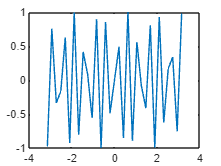

plot(x, sin(4*pi*x))

## **2.**

**Considere a experiencia aleatoria de lancar 3 vezes uma moeda equilibrada. Pretende-se estimar por simulacao a probabilidade de se obter 2 caras no fim dos 3 lancamentos. Para estimar a probabilidade por simulacao, e necessario executar varias vezes a experiencia aleatoria de lancar 3 vezes uma moeda equilibrada e calcular a percentagem de vezes em que o resultado deu 2 caras. Em Matlab, uma forma possıvel de implementar este simulador e a seguinte (assumindo que a experiencia e executada 10000 vezes):**

**(a) Implemente no Matlab as 2 versoes de codigo fornecidas.**

%% Codigo 1
% Gerar uma matriz com 3 linhas e 10000 colunas de numeros aleatorios
% entre 0.0 e 1.0 (ou seja, cada coluna representa uma experiencia):
experiencias = rand(3,10000);
% Gerar uma matriz com 3 linhas e 10000 colunas com o valor 1 se o valor
% da matriz anterior for superior a 0.5 (ou seja, se saiu cara) ou com o
% valor 0 caso contr´ario (ou seja, saiu coroa):
lancamentos = experiencias > 0.5; % 0.5 corresponde a 1 - prob. de caras
% Gerar um vetor linha com 10000 elementos com a soma dos valores de cada
% coluna da matriz anterior (ou seja, o n´umero de caras de cada experiˆencia):
resultados= sum(lancamentos);
% Gerar um vetor linha com 10000 elementos com o valor 1 quando o valor do
% vetor anterior é 2 (ou seja, se a experiencia deu 2 caras) ou 0 quando é
% diferente de 2:
sucessos= resultados==2;
% Determinar o resultado final dividindo o numero de experiencias com 2
% caras pelo n´umero total de experiˆencias:
probSimulacao= sum(sucessos)/10000

probSimulacao = 0.3691


%% Codigo 2
N= 1e5; %n´umero de experiˆencias
p = 0.5; %probabilidade de cara
k = 2; %n´umero de caras
n = 3; %n´umero de lanc¸amentos
lancamentos = rand(n,N) > p;
sucessos= sum(lancamentos)==k;
probSimulacao= sum(sucessos)/N

probSimulacao = 0.3750

**(b) Estime, usando as 2 versoes do codigo, a probabilidade de obter 2 caras em 3 lancamentos de uma moeda equilibrada (execute varias vezes a simulacao).**

%% Aproximadamente 0.38

## ** 3.**

**Estime a probabilidade de obter 6 caras em 15 lancamentos de uma moeda equilibrada?**

N= 1e5;
p = 0.5;
k = 6;
n = 15;
lancamentos = rand(n,N) > p;
sucessos= sum(lancamentos)==k;
probSimulacao= sum(sucessos)/N

probSimulacao = 0.1522

## **4.**

**Qual é a probabilidade de obter pelo menos 6 caras em 15 lancamentos de uma moeda equilibrada?**

%% Aproximadamente 0.15

## 5.

**Para facilitar o calculo de outras situacoes similares as que tratou nos pontos anteriores, crie uma funcao em Matlab que permita estimar a probabilidade por simulacao. A funcao deve ter os seguintes parametros de entrada: p, numero de lancamentos, numero de caras pretendidas e numero de experiencias a realizar. Deve utilizar nomes adequados para a funcao e para os parametros de entrada.**

**(a) Aplique a funcao para voltar a estimar as probabilidades das questoes anteriores assim como estimar as probabilidades para todo o espaco de amostragem para os seguintes numeros de lancamentos: 20, 40 e 100.**

p = 0.5;
N = 10000;
k = 20;
prob = zeros(1, k+1); %% Inicialização do vetor para alocar imediatamente todo o espaço necessário
for i = 0:k
    prob(i+1) = coinThrowHeadsCalculator(p, k, i, N);
end


**(b) Faca 3 graficos, usando a funcao stem, das probabilidades estimadas para 20, 40 e 100 lancamentos.**

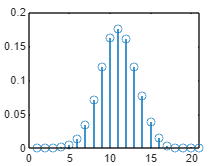

p = 0.5;
N = 10000;
k = 20;
prob20 = zeros(1, k+1); %% Inicialização do vetor para alocar imediatamente todo o espaço necessário
for i = 0:k
    prob20(i+1) = coinThrowHeadsCalculator(p, k, i, N);
end

p = 0.5;
N = 10000;
k = 40;
prob40 = zeros(1, k+1); %% Inicialização do vetor para alocar imediatamente todo o espaço necessário
for i = 0:k
    prob40(i+1) = coinThrowHeadsCalculator(p, k, i, N);
end

p = 0.5;
N = 10000;
k = 100;
prob100 = zeros(1, k+1); %% Inicialização do vetor para alocar imediatamente todo o espaço necessário
for i = 0:k
    prob100(i+1) = coinThrowHeadsCalculator(p, k, i, N);
end

stem(prob20)

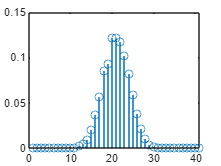

stem(prob40)

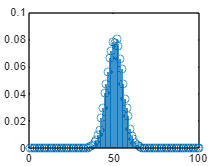

stem(prob100)

## **6.**

**Calcule o valor analitico para cada um dos problemas anteriores e compare os resultados obtidos com os valores estimados.**

p = 0.5;
k =2 % k determina o numero de caras desejado

k = 2

n = 4% n significa o numero de lançamentos

n = 4

prob= nchoosek(n,k)*p^k*(1-p)^(n-k) 

prob = 0.3750

%% Probabilidade da experiência em questão determinado analiticamente





## **7.**

**Considere um processo de producao fabril que produz torneiras em que a probabilidade de cada torneira ser produzida com defeito é de 30%. No processo de controlo de qualidade, é selecionada uma amostra de 5 peças.**

**(a) Calcule analiticamente e por simulacao a probabilidade de 3 pecas da amostra serem defeituosas.**

%% Analiticamente
p = 0.30;
k = 3;
n = 5;
prob= nchoosek(n,k)*p^k*(1-p)^(n-k) % 10 * 0.3^3 * 0.7^2

prob = 0.1323


%% Simulação
N = 1e5;
% Podemos usar a função criada anteriormente para este caso, mas para tal
% temos que alterar o valor de p, tendo em consideração que a prob de uma
% peça ser defeituosa é 0.30, logo a probabilidade de não o ser é 1-0.30 =
% 0.70. Portanto uma peça só defeituosa se os valores da experiencia forem
% > 0.70.
prob = coinThrowHeadsCalculator(0.70, 5, 3, N) 

prob = 0.1312

**(b) Calcule analiticamente e por simulacao a probabilidade de, no maximo, 2 das pecas da amostra serem defeituosas.**

%% Analiticamente
p = 0.30;
n = 5;
probArrayA = zeros(1,4);
for k = [0 1 2]
    probArrayA(k+1) = nchoosek(n,k)*p^k*(1-p)^(n-k);
end

probFinalA = sum(probArrayA)

probFinalA = 0.8369


%% Por simulação
N = 10000;
probArrayS = zeros(1,4);
for k = [0 1 2]
    probArrayS(k+1) = coinThrowHeadsCalculator(1-p, n, k, N);
end

probFinalS = sum(probArrayS)

probFinalS = 0.8376

**(c) Baseado em simulacao, construa no Matlab o histograma representativo da distribuicao de probabilidades do numero de peças defeituosas da amostra.**

p = 0.30;
n = 5;
probArrayHistogram = zeros(1,6);
for k = [0 1 2 3 4 5]
    probArrayHistogram(k+1) = coinThrowHeadsCalculator(1-p, n, k, N);
end

x = [0 1 2 3 4 5]

x =      0     1     2     3     4     5


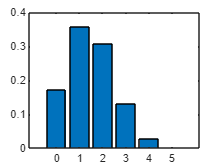

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [0 1 2 3 4 5]
        YData: [0.1709 0.3561 0.3081 0.1314 0.0280 0.0021]

  Show all properties



b = bar(x, probArrayHistogram)

function[probSim] = coinThrowHeadsCalculator(prob, nThrows, nHeads, nSamples)

headsCount = rand(nThrows, nSamples) > prob;
successes = sum(headsCount) == nHeads;
probSim = sum(successes) / nSamples;
end